close all;

angle_condition = 95.7221726498029;
z_1 = discrete_desired_poles(1)

z_1 = 0.9580 + 0.0411i

G_lead = zpk([0.965], [365.193637941578e-003], 121.136307447244, T)

G_lead =
 
  121.14 (z-0.965)
  ----------------
     (z-0.3652)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.




K_u = 1;
K_c = 1.5;

K_d = K_u / K_c;

z_p = 0.999

z_p = 0.9990

z_0 = 1 - (1 - z_p)/K_d

z_0 = 0.9985

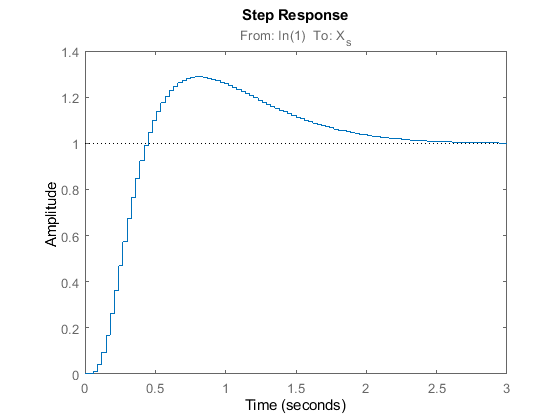


G_lag = zpk([z_0], [z_p], 1.4, T);

%hold on;
%rlocus(G_lead * G_lag * G_p);
%scatter(real(discrete_desired_poles), imag(discrete_desired_poles), 'r+');
%hold off;

step(feedback(G_p * G_lead * G_lag, 1))

stepinfo(feedback(G_p * G_lead * G_lag, 1))

ans = struct with fields:
        RiseTime: 0.2400
    SettlingTime: 2.2200
     SettlingMin: 0.9238
     SettlingMax: 1.2876
       Overshoot: 28.7607
      Undershoot: 0
            Peak: 1.2876
        PeakTime: 0.8100



%t = 1:0.1:5;
%output = arrayfun(@(x) stepinfo(feedback(x * G_p * G_lead * G_lag, 1)).Overshoot, t);
%plot(t, output)